Forecast monthly runoff with ARIMA

## 1 Clear workspace

clear
close all
clc

## 2 Read monthly runoff

data_path='../time_series/';
station='Huaxian' %'Huaxian', 'Xianyang' or 'Zhangjiashan'

station = 'Huaxian'

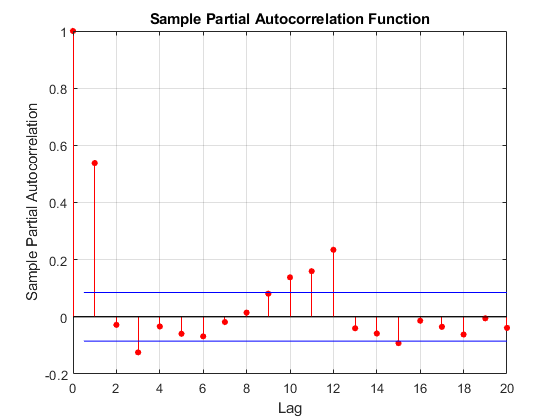

switch station
    case 'Huaxian'
        save_path = '../Huaxian/projects/arma/';
        data = xlsread([data_path,'HuaxianRunoff1951-2018(1953-2018).xlsx'],1,'B26:B817');%full=792samples
    
    case 'Xianyang'
        save_path = '../Xianyang/projects/arma/';
        data = xlsread([data_path,'XianyangRunoff1951-2018(1953-2018).xlsx'],1,'B26:B817');%full=792samples
        
    case 'Zhangjiashan'
        save_path = '../Zhangjiashan/projects/arma/';
        data = xlsread([data_path,'ZhangJiaShanRunoff1953-2018(1953-2018).xlsx'],1,'B2:B793');%full=792samples
end

if exist(save_path,'dir')==0
   mkdir(save_path);
end

train_len = 552;
dev_len=120;
test_len=120;

train = data(1:train_len);
dev = data(train_len+1:train_len+dev_len);
test = data(train_len+dev_len+1:length(data));

parcorr(train)

autocorr(train)

## 3 Tune ARIMA models


mse = zeros(20,20);
parfor p =1:20
    for q=1:20
        m = armax(train,[p,q]);
        dev_pred = predict(m,dev,1);
        mse(p,q)= (sum((dev-dev_pred).^2)/length(dev));
    end
end


## 4 Predict the train, dev and test set

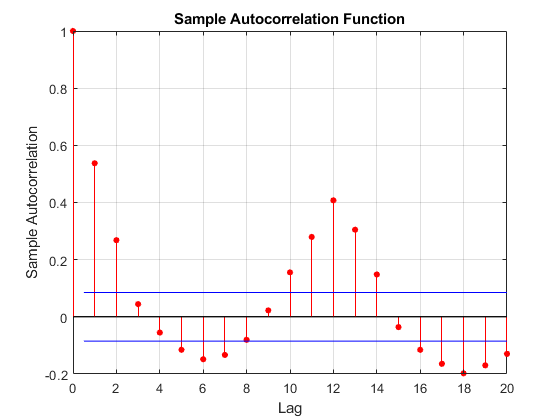

minimum = min(min(mse));
[p_,q_]=find(mse==minimum);
m = armax(train,[p_,q_]);

train_pred = predict(m,train,1);
dev_pred = predict(m,dev,1);
test_pred = predict(m,test);

train_pred(train_pred<0)=0;
dev_pred(dev_pred<0)=0;
test_pred(test_pred<0)=0;

nse_train = NSE(train,train_pred);
nse_dev = NSE(dev,dev_pred);
nse_test = NSE(test,test_pred);

nrmse_train =NRMSE(train,train_pred);
nrmse_dev = NRMSE(dev,dev_pred);
nrmse_test = NRMSE(test,test_pred);

ppts_train = PPTS(train,train_pred,5);

y_true_ =    43.7901
   40.1760
   38.5716
   36.7589
   36.6284
   34.7933
   34.3760
   31.6051
   29.2352
   29.0805


y_true_order =    141
    68
   274
   345
   370
   189
   142
    55
   106
   381


y_pred_ =    18.8639
   18.1571
   15.9707
   18.9090
   14.6656
   17.2135
   25.1668
   16.4600
    7.5431
   17.0888


ppts_dev = PPTS(dev,dev_pred,5);

y_true_ =    29.8279
   25.1165
   13.4997
   11.8809
   11.2257
   10.6223
   10.1503
    7.7388
    7.5529
    7.5077


y_true_order =     58
    82
     7
   106
    56
    22
    80
   104
    79
   103


y_pred_ =     8.9970
   10.5801
    7.4851
   10.3341
    5.9735
    7.5680
    9.8528
   10.6004
    3.2440
    2.4909


ppts_test = PPTS(test,test_pred,5);

y_true_ =    32.3767
   24.7216
   18.6783
   15.8656
   14.9455
   13.2451
   13.0836
   11.1387
   10.3715
    9.4003


y_true_order =     33
   115
    55
    20
   106
    69
    45
    21
    34
    56


y_pred_ =    14.9301
    6.8902
    9.6052
    9.8569
    4.9499
    9.2181
   12.9479
   12.5022
   16.0468
   12.9881


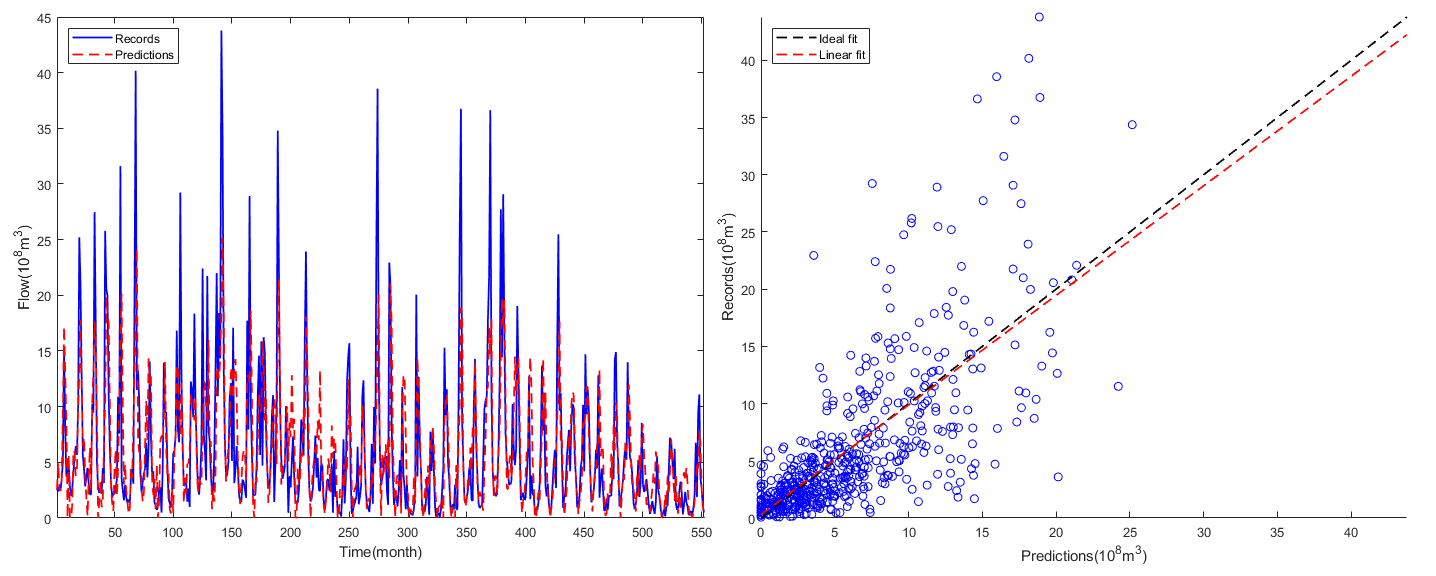

ha =     1.0044
    2.0044


x =          0    0.4423    0.8846    1.3270    1.7693    2.2116    2.6539    3.0963    3.5386    3.9809    4.4232    4.8656    5.3079    5.7502    6.1925    6.6349    7.0772    7.5195    7.9618    8.4042    8.8465    9.2888    9.7311   10.1735   10.6158   11.0581   11.5004   11.9428   12.3851   12.8274   13.2697   13.7121   14.1544   14.5967   15.0390   15.4814   15.9237   16.3660   16.8083   17.2507   17.6930   18.1353   18.5776   19.0199   19.4623   19.9046   20.3469   20.7892   21.2316   21.6739


c =     0.9578    0.2971


y =     0.2971    0.7207    1.1444    1.5681    1.9918    2.4154    2.8391    3.2628    3.6864    4.1101    4.5338    4.9575    5.3811    5.8048    6.2285    6.6522    7.0758    7.4995    7.9232    8.3469    8.7705    9.1942    9.6179   10.0415   10.4652   10.8889   11.3126   11.7362   12.1599   12.5836   13.0073   13.4309   13.8546   14.2783   14.7019   15.1256   15.5493   15.9730   16.3966   16.8203   17.2440   17.6677   18.0913   18.5150   18.9387   19.3624   19.7860   20.2097   20.6334   21.0570


y = 0.95783*x + 0.29706


ans =     0.9578    0.2971



metrics=[p_,q_,nse_train,nrmse_train,ppts_train,nse_dev,nrmse_dev,ppts_dev,nse_test,nrmse_test,ppts_test];
metrics_table = array2table(metrics, 'VariableNames', {'p','q','nse_train','nrmse_train','ppts_train','nse_dev','nrmse_dev','ppts_dev','nse_test','nrmse_test','ppts_test'});
writetable(metrics_table, strcat(save_path,'metrics.csv'));
train_results=[train,train_pred];
dev_results=[dev,dev_pred];
test_results=[test,test_pred];
train_table=array2table(train_results, 'VariableNames',{'train_y','train_pred'});
dev_table=array2table(dev_results, 'VariableNames',{'dev_y','dev_pred'});
test_table=array2table(test_results, 'VariableNames',{'test_y','test_pred'});
writetable(train_table, strcat(save_path,'train_pred.csv'));
writetable(dev_table, strcat(save_path,'dev_pred.csv'));
writetable(test_table, strcat(save_path,'test_pred.csv'));

plot_pred(train,train_pred,strcat(save_path,'train_pred.png'))

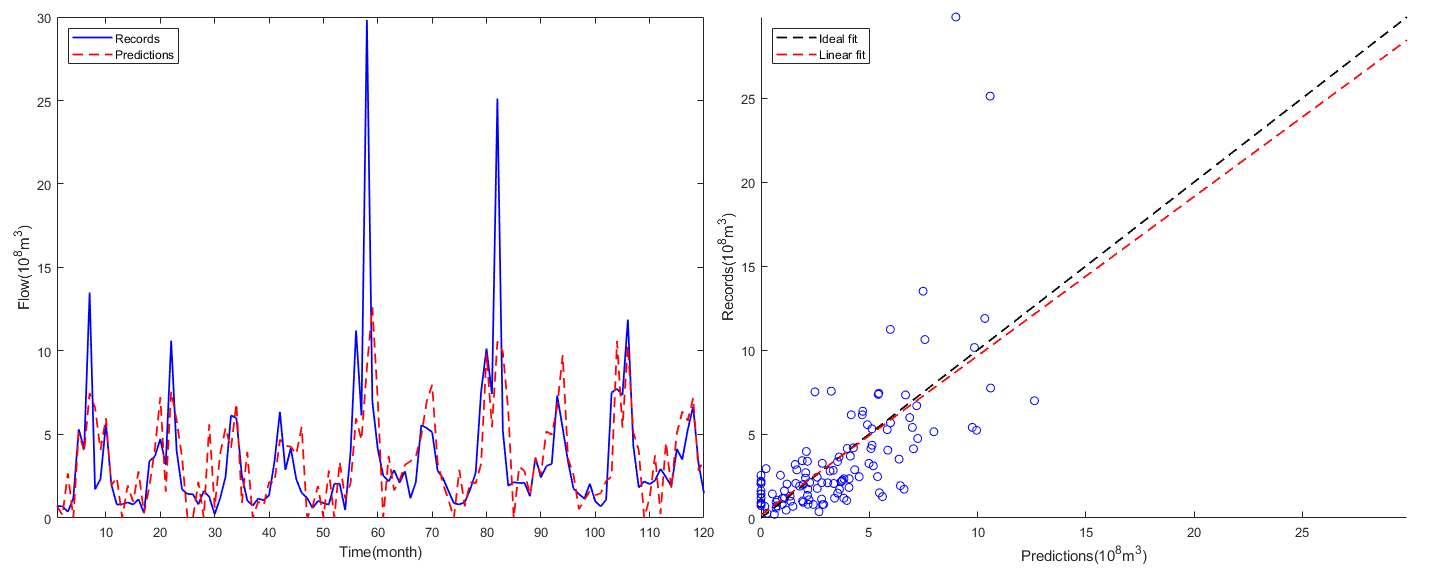

ha =     3.0044
    4.0044


x =          0    0.3013    0.6026    0.9039    1.2052    1.5065    1.8077    2.1090    2.4103    2.7116    3.0129    3.3142    3.6155    3.9168    4.2181    4.5194    4.8207    5.1220    5.4232    5.7245    6.0258    6.3271    6.6284    6.9297    7.2310    7.5323    7.8336    8.1349    8.4362    8.7375    9.0387    9.3400    9.6413    9.9426   10.2439   10.5452   10.8465   11.1478   11.4491   11.7504   12.0517   12.3530   12.6542   12.9555   13.2568   13.5581   13.8594   14.1607   14.4620   14.7633


c =     0.9482    0.1715


y =     0.1715    0.4572    0.7429    1.0286    1.3143    1.6000    1.8857    2.1714    2.4571    2.7427    3.0284    3.3141    3.5998    3.8855    4.1712    4.4569    4.7426    5.0283    5.3140    5.5996    5.8853    6.1710    6.4567    6.7424    7.0281    7.3138    7.5995    7.8852    8.1708    8.4565    8.7422    9.0279    9.3136    9.5993    9.8850   10.1707   10.4564   10.7421   11.0277   11.3134   11.5991   11.8848   12.1705   12.4562   12.7419   13.0276   13.3133   13.5989   13.8846   14.1703


y = 0.94822*x + 0.17154


ans =     0.9482    0.1715


plot_pred(dev,dev_pred,strcat(save_path,'dev_pred.png'))

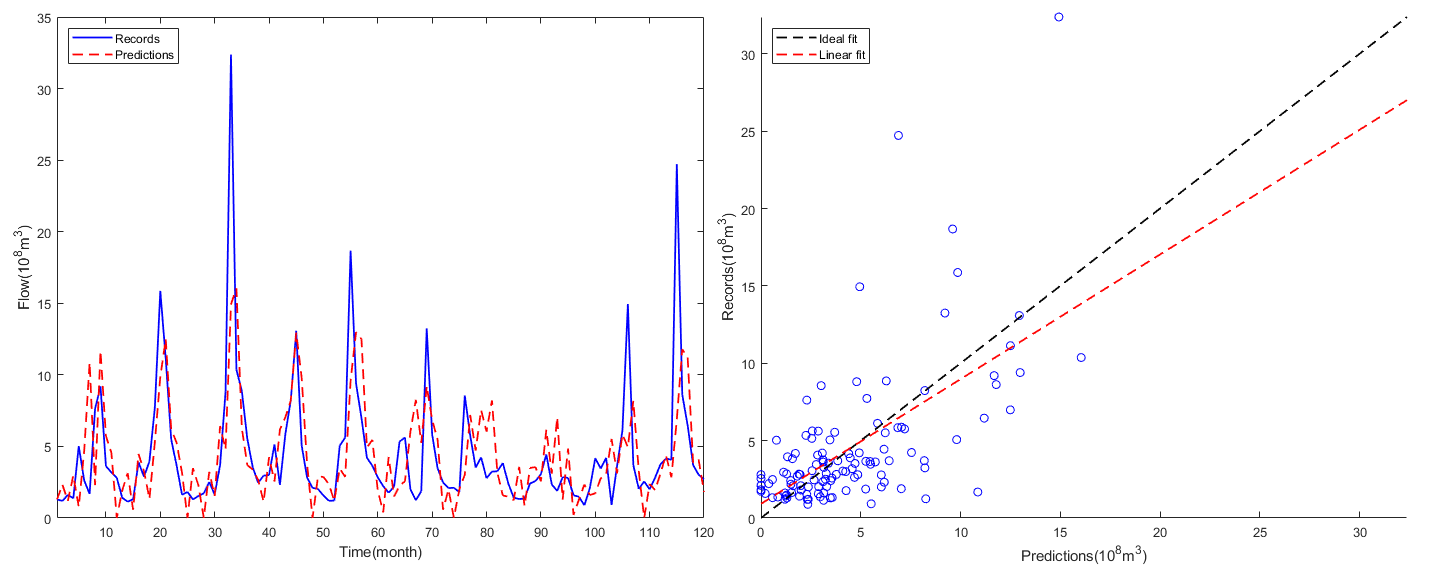

ha =     5.0044
    6.0044


x =          0    0.3270    0.6541    0.9811    1.3081    1.6352    1.9622    2.2893    2.6163    2.9433    3.2704    3.5974    3.9244    4.2515    4.5785    4.9056    5.2326    5.5596    5.8867    6.2137    6.5407    6.8678    7.1948    7.5219    7.8489    8.1759    8.5030    8.8300    9.1570    9.4841    9.8111   10.1381   10.4652   10.7922   11.1193   11.4463   11.7733   12.1004   12.4274   12.7544   13.0815   13.4085   13.7356   14.0626   14.3896   14.7167   15.0437   15.3707   15.6978   16.0248


c =     0.8058    0.9156


y =     0.9156    1.1792    1.4427    1.7062    1.9697    2.2333    2.4968    2.7603    3.0239    3.2874    3.5509    3.8144    4.0780    4.3415    4.6050    4.8685    5.1321    5.3956    5.6591    5.9226    6.1862    6.4497    6.7132    6.9767    7.2403    7.5038    7.7673    8.0308    8.2944    8.5579    8.8214    9.0849    9.3485    9.6120    9.8755   10.1390   10.4026   10.6661   10.9296   11.1932   11.4567   11.7202   11.9837   12.2473   12.5108   12.7743   13.0378   13.3014   13.5649   13.8284


y = 0.8058*x + 0.91564


ans =     0.8058    0.9156


plot_pred(test,test_pred,strcat(save_path,'test_pred.png'))